# Laboratorio grupal. Explorando la farmacocinética y farmacodinámica del paracetamol: un enfoque práctico en Matlab y Simulink

**Autores: **Javier Blanco Álvarez, Pablo Castañeda Fuentes, Lucía Royo Pascual, Ferrán Soto Moscardó, Jesús Gallinal Moreno

**Objetivos**

Los objetivos del trabajo son los siguientes:

- Evaluar el impacto del cambio en la dosis inicial del fármaco en las concentraciones plasmáticas y efectivas a lo largo del tiempo, analizando cómo diferentes dosis afectan la cinética del fármaco y su efecto terapéutico.

- Investigar cómo la tasa de eliminación del fármaco (parámetro K) afecta la duración y magnitud del efecto terapéutico, examinando cómo variaciones en la tasa de eliminación influyen en las concentraciones plasmáticas y efectivas del fármaco.

- Analizar el efecto de ajustar la tasa de infusión (parámetro F) en las concentraciones plasmáticas y efectivas del fármaco, explorando cómo diferentes tasas de administración impactan en la cinética del fármaco y su efecto terapéutico.

- Utilizar herramientas de modelado y simulación, como MATLAB y Simulink, para estudiar el comportamiento del fármaco en el organismo. Mediante la aplicación de técnicas de simulación, podrán comprender mejor los principios subyacentes de la farmacocinética y la farmacodinamia.

**Descripción**

En este laboratorio, se emplea un enfoque de dos compartimentos para describir tanto la farmacocinética (PK) como la farmacodinámica (PD) de un fármaco. En este contexto, el primer compartimento representa el plasma, que actúa como un depósito inicial del fármaco en la circulación sistémica, mientras que el segundo compartimento puede referirse a tejidos u otros órganos del cuerpo donde el fármaco se distribuye y ejerce su efecto.

 Este enfoque de dos compartimentos nos permite comprender cómo el fármaco se absorbe, se distribuye, se metaboliza y se elimina en el organismo, así como cómo estos procesos se relacionan con su efecto farmacológico.

 Las ecuaciones diferenciales asociadas con este modelo nos proporcionan una herramienta para simular y estudiar cómo varían las concentraciones de fármaco en el tiempo en diferentes compartimentos del cuerpo, así como su efecto biológico en el sitio de acción. 

 Las ecuaciones diferenciales que gobiernan el modelo son las siguientes:


$$\frac{dC_{gut} }{dt}=\ {-K}_a C_{gut}$$



$$\frac{dC_1 }{dt}=-k_{12} C_1 +k_{21} C_2 -KC_1 +FK_a C_{gut}$$



$$\begin{array}{l}
\frac{dC_2 }{dt}=\ k_{12} C_1 -k_{21} C_2 \\
\frac{dC_e }{dt}=\ k_{e1} C_1 -k_{e0} C_e 
\end{array}$$


 Las variables del modelo incluyen $C_1$, que representa la concentración de la droga en el compartimento 1, generalmente asociado con el plasma sanguíneo o algún otro compartimento central del organismo. Por otro lado, $C_2$ denota la concentración de la droga en el compartimento 2, el cual puede simbolizar tejidos periféricos u otros compartimentos del cuerpo. Además, $C_{gut}$ refleja la concentración de la droga en el compartimento gastrointestinal, indicando la cantidad de fármaco presente en el tracto gastrointestinal en un momento dado. Finalmente, $C_e$ representa la concentración efectiva de la droga, caracterizando la cantidad de droga presente en el sitio de acción o su efecto biológico.

 Por otro lado, los parámetros del modelo comprenden $K$, que representa la constante de eliminación de la droga del compartimento 1 (plasma), indicando la velocidad a la que la droga abandona este compartimento. Además, $k_{12}$ y $k_{21}$ representan las tasas de transferencia de la droga entre el compartimento 1 y el compartimento 2, respectivamente, describiendo cómo la droga se mueve entre estos dos compartimentos. $K_a$ denota la tasa de absorción de la droga desde el tracto gastrointestinal al compartimento 1, mientras que $k_{e1}$ y $k_{\mathrm{e0}}$son las tasas de eliminación de la droga desde el compartimento 1 y el compartimento efectivo, respectivamente. Finalmente, $F$ representa la fracción de la dosis que se absorbe en el tracto gastrointestinal y contribuye al compartimento 1. Los valores de los parámetros se recogen en la tabla siguiente:

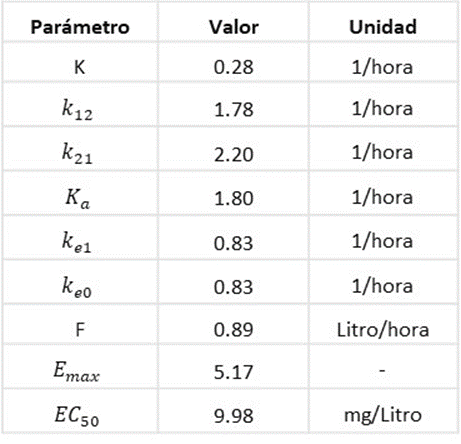

Tabla 1. Fuente: elaboración propia. 

Las principales propiedades farmacodinámicas comprenden el efecto máximo ($E_{max}$) y la concentración que genera el 50 % del máximo efecto ($EC_{50}$). La relación entre la concentración del fármaco y su efecto puede ser descripta mediante la ecuación de Hill [3],


$$Effect=E_0 -\frac{E_{max\ } \ C_e^n }{EC_{50}^n \ \ +\ \ C_e^n }$$


donde  representa la respuesta basal,  indica el cambio máximo en el efecto,  es la concentración en el compartimento del efecto,  es la concentración que produce el 50 % de , y   es el coeficiente de Hill [3], que define la pendiente de la curva. En este laboratorio,  y .

**Preguntas**

- Desarrolle el modelo en Simulink, mostrando los diversos bloques que componen la estructura del sistema. Proporcione una captura de pantalla del modelo de bloques resultante, identificando y explicando la función de cada bloque utilizado en la simulación del modelo PK/PD. 

- Configure el tiempo de simulación en ocho horas para investigar las variaciones iniciales de las concentraciones plasmáticas y efectivas del paracetamol poco después de su administración. Para las condiciones iniciales, podríamos establecer que la concentración inicial en el compartimento 1 es de 1000mg/L, mientras que las demás concentraciones se establecen en cero excepto la concentración inicial en el compartimento de Gut que se encuentra en 200mg/L. Esta configuración permite explorar cómo los residuos de fármacos no absorbidos en el tracto gastrointestinal pueden afectar la absorción y distribución del paracetamol en el organismo, proporcionando una perspectiva más completa de su cinética y efecto terapéutico.

- ¿Cómo afecta el cambio en la dosis inicial del fármaco a las concentraciones plasmáticas y efectivas a lo largo del tiempo? Comparemos el impacto de diferentes dosis iniciales de paracetamol (por ejemplo, 400 mg, 600 mg y 1000 mg) mediante medidas estándar, como la concentración plasmática máxima (Cmax), el tiempo necesario para alcanzarla (Tmax), el área bajo la curva de concentración plasmática frente al tiempo (AUC) y la concentración efectiva en momentos específicos, como el instante en que se alcanza el efecto máximo (Emax).

- ¿Cómo afecta la tasa de eliminación del fármaco (parámetro ) a la duración y magnitud del efecto terapéutico?

- ¿Cómo varía la concentración plasmática del fármaco en respuesta a cambios en la tasa de administración (parámetro )?

**Modelo Simulink y Matlab**

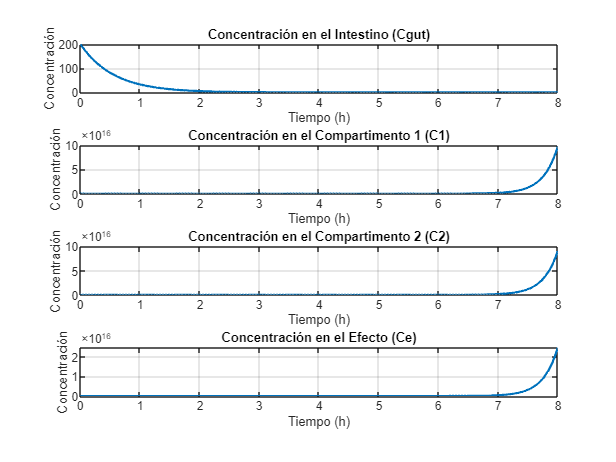

clc; clear all;

% Cargar y configurar el modelo de Simulink
modelo = 'Laboratorio_grupal_simulink'; % Nombre del modelo (sin extensión .slx)
load_system(modelo); % Cargar el modelo en MATLAB

%SIMULACIÓN T=8h
% Configurar parámetros de simulación si es necesario
set_param(modelo, 'StopTime', '8'); % Configurar tiempo de simulación (opcional)

% Ejecutar la simulación
out = sim(modelo);

%Extracción de variables
Cgut = out.Cgut; % Valores de Cgut
C1 = out.C1; % Valores de C1
C2 = out.C2; % Valores de C2
Ce = out.Ce; % Valores de Ce
effect=out.effect;

%Plots
% Crear los subplots
figure;

% Subplot 1: Concentración en el intestino (Cgut)
subplot(4,1,1);
plot(Cgut.Time, Cgut.Data, 'LineWidth', 1.5);
title('Concentración en el Intestino (Cgut)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 2: Concentración en el compartimento 1 (C1)
subplot(4,1,2);
plot(C1.Time, C1.Data, 'LineWidth', 1.5);
title('Concentración en el Compartimento 1 (C1)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 3: Concentración en el compartimento 2 (C2)
subplot(4,1,3);
plot(C2.Time, C2.Data, 'LineWidth', 1.5);
title('Concentración en el Compartimento 2 (C2)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

% Subplot 4: Concentración en el efecto (Ce)
subplot(4,1,4);
plot(Ce.Time, Ce.Data, 'LineWidth', 1.5);
title('Concentración en el Efecto (Ce)');
xlabel('Tiempo (h)');
ylabel('Concentración');
grid on;

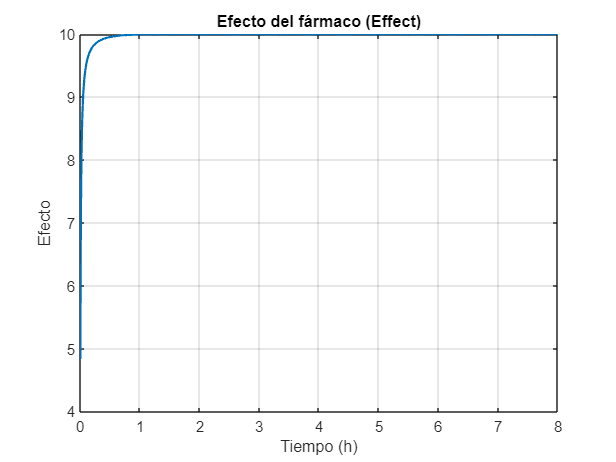

%CALCULO DE EFECTO MAXIMO
%Plots
figure;

plot(effect.Time, effect.Data, 'LineWidth', 1.5);
title('Efecto del fármaco (Effect)');
xlabel('Tiempo (h)');
ylabel('Efecto');
grid on;